# Sparse Representation in Dirac DCT basis

close all;
clearvars;
clc;
rng('default');
png_export = true;
pdf_export = false;
% Create the directory for storing images
[status_code,message,message_id] = mkdir('bin');


## Problem Setup

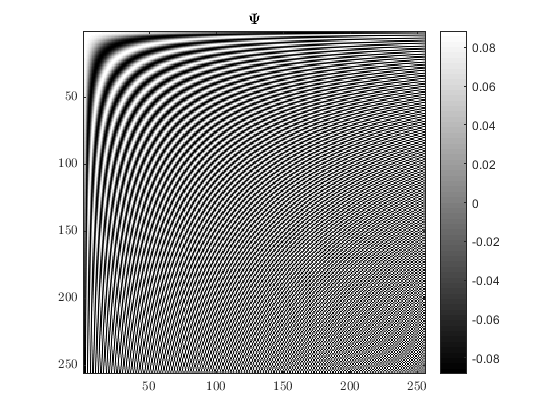


% Signal space dimension
N = 256;
% Representation space dimension
D = N + N;

% Constructing a Dirac DCT dictionary
I = eye(N);
Psi = dctmtx(N)';
Phi = [I  Psi];

% Visualizing the DCT basis
imagesc(Psi) ;
colormap(gray);
colorbar;
axis image;
title('\Psi');
if png_export
export_fig bin\dct_256.png -r120 -nocrop;
end

if pdf_export
export_fig bin\dct_256.pdf;
end

## Dictionary

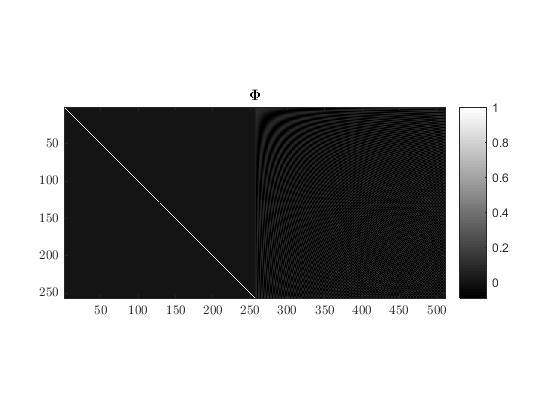

% Visualizing the dictionary
imagesc(Phi) ;
colormap(gray);
colorbar;
axis image;
title('\Phi');
if png_export
export_fig bin\dirac_dct_256.png -r120 -nocrop;
end

if pdf_export
export_fig bin\dirac_dct_256.pdf;
end

% A combination of impulses and cosines.
alpha = zeros(D, 1);
alpha(20) = 1;
alpha(30) = -.4;
alpha(100) = .6;
alpha(N + 4) = 1.2;
alpha(N + 58) = -.8;
x = Phi * alpha;
K  = 5;

% Finding the representation in DCT 
x_dct = Psi' * x;

## Impulses + Cosines

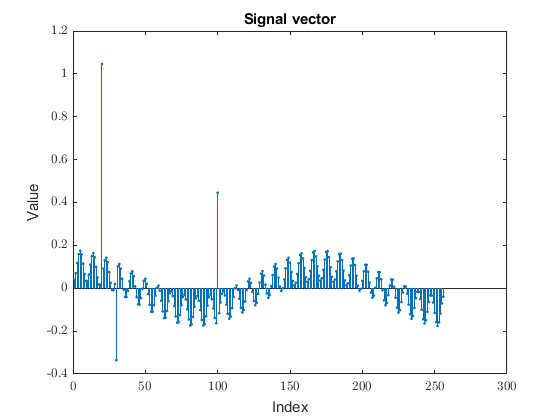

stem(x, '.');
xlabel('Index');
ylabel('Value');
title('Signal vector');
if png_export
export_fig bin\impulse_cosine_combination_signal.png -r120 -nocrop;
end

if pdf_export
export_fig bin\impulse_cosine_combination_signal.pdf;
end

## Impulses + Cosines DCT representation

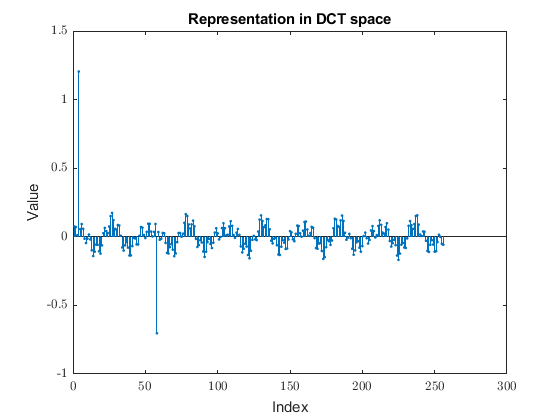

stem(x_dct, '.');
xlabel('Index');
ylabel('Value');
title('Representation in DCT space');
if png_export
export_fig bin\impulse_cosine_dct_basis.png -r120 -nocrop;
end

if pdf_export
export_fig bin\impulse_cosine_dct_basis.pdf;
end


## Sparse representation in Dirac DCT dictionary

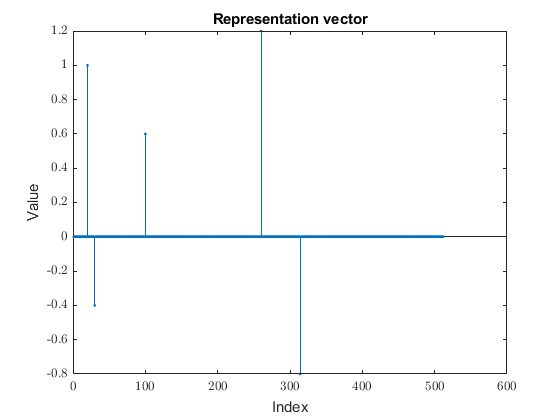

stem(alpha, '.');
xlabel('Index');
ylabel('Value');
title('Representation vector');
if png_export
export_fig bin\impulse_cosine_dirac_dct.png -r120 -nocrop;
end

if pdf_export
export_fig bin\impulse_cosine_dirac_dct.pdf;
end

## Matching Pursuit

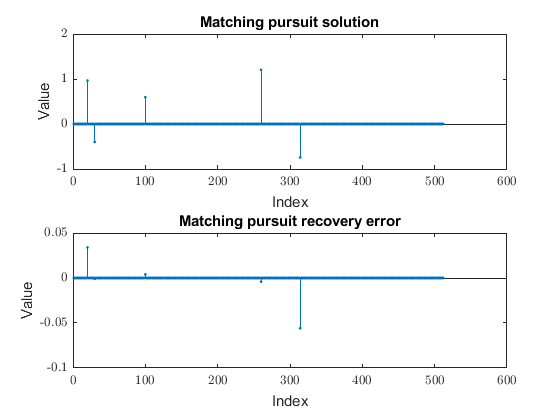

solver = spx.pursuit.single.MatchingPursuit(Phi, K);
result = solver.solve(x);
mp_solution = result.z;
figure;
subplot(211);
stem(mp_solution, '.');
xlabel('Index');
ylabel('Value');
title('Matching pursuit solution');
mp_diff = alpha - mp_solution;
subplot(212);
stem(mp_diff, '.');
xlabel('Index');
ylabel('Value');
title('Matching pursuit recovery error');
if png_export
export_fig bin\dirac_dct_mp_solution.png -r120 -nocrop;
end

if pdf_export
export_fig bin\dirac_dct_mp_solution.pdf;
end

% Recovery error
mp_recovery_error = norm(mp_diff) / norm(x);
fprintf('Matching pursuit recovery error: %0.4f\n', mp_recovery_error);

Matching pursuit recovery error: 0.0353


## Orthogonal Matching Pursuit

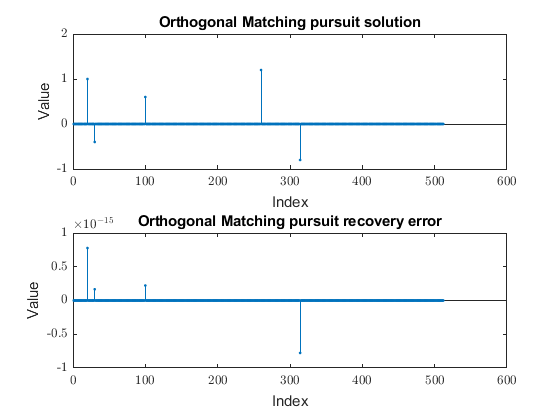

solver = spx.pursuit.single.OrthogonalMatchingPursuit(Phi, K);
result = solver.solve(x);
omp_solution = result.z;
figure;
subplot(211);
stem(omp_solution, '.');
xlabel('Index');
ylabel('Value');
title('Orthogonal Matching pursuit solution');
omp_diff = alpha - omp_solution;
subplot(212);
stem(omp_diff, '.');
xlabel('Index');
ylabel('Value');
title('Orthogonal Matching pursuit recovery error');
if png_export
export_fig bin\dirac_dct_omp_solution.png -r120 -nocrop;
end

if pdf_export
export_fig bin\dirac_dct_omp_solution.pdf;
end

Recovery error

omp_recovery_error = norm(omp_diff) / norm(x);
fprintf('Orthogonal Matching pursuit recovery error: %0.4f\n', omp_recovery_error);

Orthogonal Matching pursuit recovery error: 0.0000


## Basis Pursuit

solver = spx.pursuit.single.BasisPursuit(Phi, x);
result = solver.solve_l1_noise();

.


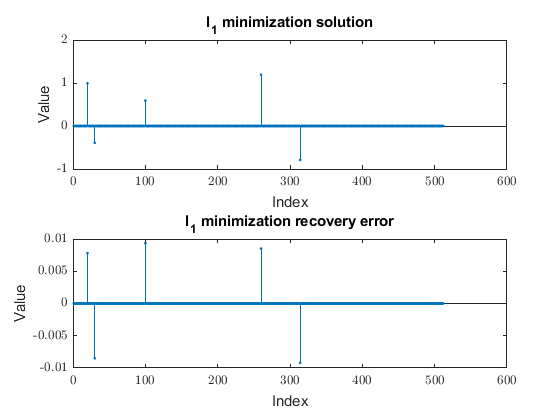

l1_solution = result;
figure;
subplot(211);
stem(l1_solution, '.');
xlabel('Index');
ylabel('Value');
title('l_1 minimization solution');
l1_diff = alpha - l1_solution;
subplot(212);
stem(l1_diff, '.');
xlabel('Index');
ylabel('Value');
title('l_1 minimization recovery error');
if png_export
export_fig bin\dirac_dct_l_1_solution.png -r120 -nocrop;
end

if pdf_export
export_fig bin\dirac_dct_l_1_solution.pdf;
end

Recovery error

l1_recovery_error = norm(l1_diff) / norm(x);
fprintf('l_1 recovery error: %0.4f\n', l1_recovery_error);

l_1 recovery error: 0.0104
